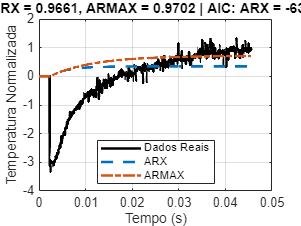

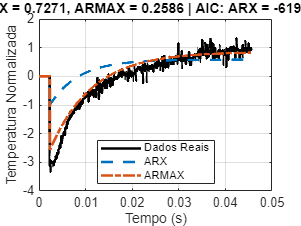

%% Identificação de Sistemas com AIC Corrigido (Dados Normalizados)
clc; clear; close all;


% === 1. Leitura dos Dados ===
% Certifique-se de que o arquivo '1507.xlsx' está na mesma pasta
% ou adicione o caminho completo.
dados = readmatrix('1507.xlsx');
tempo_original = dados(:,1); % Renomeado para clareza
y_raw = dados(:,2);      % Temperatura original


% === 2. Pré-processamento (SEÇÃO CORRIGIDA) ===
% Normalização da saída
y_mean = mean(y_raw);
y_std = std(y_raw);
y_norm_temp = (y_raw - y_mean) / y_std; % Normaliza os dados originais

% Adiciona o repouso (50 amostras) ao início da saída y_norm
y_norm = [zeros(50,1); y_norm_temp];

% ATUALIZA o número de amostras N para o NOVO tamanho de y_norm
N = length(y_norm);

% AGORA, cria o sinal de entrada u_norm com o mesmo tamanho N
u_norm = [zeros(50,1); ones(N-50,1)];

% Cria o novo vetor de tempo compatível com o tamanho N final
dt = tempo_original(2) - tempo_original(1); % Calcula dt dos dados originais
tempo = (0:dt:(N-1)*dt)';


% === 3. Inicialização ===
ordens = [1 2];
nk = 1;
cores.arx = [0 0.4470 0.7410];    % azul
cores.armax = [0.8500 0.3250 0.0980]; % laranja

rmse_arx = zeros(1,2);
rmse_armax = zeros(1,2);
aic_arx = zeros(1,2);
aic_armax = zeros(1,2);
y_arx = cell(1,2);
y_armax = cell(1,2);

% === 4. Identificação ARX e ARMAX (com AIC atualizado) ===
for i = 1:length(ordens)
    na = ordens(i); nb = ordens(i); nc = ordens(i);
    
    % Dados de identificação
    data_id = [y_norm u_norm];

    % === ARX ===
    modelo_arx = arx(data_id, [na nb nk]);
    y_arx{i} = sim(modelo_arx, u_norm);
    erro_arx = y_norm - y_arx{i};
    
    rmse_arx(i) = sqrt(mean(erro_arx.^2));
    
    % Estimativa da variância dos resíduos
    sigma2_arx = (erro_arx' * erro_arx) / N;
    
    % Número de parâmetros: a + b
    d_arx = na + nb;
    
    % AIC com matriz de covariância
    aic_arx(i) = N * log(sigma2_arx) + 2 * d_arx;


    % === ARMAX ===
    modelo_armax = armax(data_id, [na nb nc nk]);
    y_armax{i} = sim(modelo_armax, u_norm);
    erro_armax = y_norm - y_armax{i};
    
    rmse_armax(i) = sqrt(mean(erro_armax.^2));
    
    % Estimativa da variância dos resíduos
    sigma2_armax = (erro_armax' * erro_armax) / N;
    
    % Número de parâmetros: a + b + c
    d_armax = na + nb + nc;
    
    % AIC com matriz de covariância
    aic_armax(i) = N * log(sigma2_armax) + 2 * d_armax;
end

% === 5. Gráficos ===
for i = 1:2
    figure('Name', sprintf('Modelos ARX e ARMAX - Ordem %d', ordens(i)));
    plot(tempo, y_norm, 'k-', 'LineWidth', 2); hold on;
    plot(tempo, y_arx{i}, '--', 'Color', cores.arx, 'LineWidth', 2);
    plot(tempo, y_armax{i}, '-.', 'Color', cores.armax, 'LineWidth', 2);
    title(sprintf('Ordem %d | RMSE: ARX = %.4f, ARMAX = %.4f | AIC: ARX = %.2f, ARMAX = %.2f', ...
        ordens(i), rmse_arx(i), rmse_armax(i), aic_arx(i), aic_armax(i)));
    xlabel('Tempo (s)');
    ylabel('Temperatura Normalizada');
    legend('Dados Reais', 'ARX', 'ARMAX', 'Location', 'best');
    grid on;
    hold off;
end



% === 6. Tabela no Console ===
fprintf('\n=== Desempenho com Dados Normalizados + Repouso ===\n');


=== Desempenho com Dados Normalizados + Repouso ===


fprintf('Modelo | Ordem |   RMSE   |    AIC    \n');

Modelo | Ordem |   RMSE   |    AIC    


fprintf('-------|-------|----------|-----------\n');

-------|-------|----------|-----------


for i = 1:length(ordens)
    fprintf('ARX    |   %d   | %.5f | %.2f\n', ordens(i), rmse_arx(i), aic_arx(i));
end

ARX    |   1   | 0.96607 | -63.93
ARX    |   2   | 0.72711 | -619.14


for i = 1:length(ordens)
    fprintf('ARMAX  |   %d   | %.5f | %.2f\n', ordens(i), rmse_armax(i), aic_armax(i));
end

ARMAX  |   1   | 0.97019 | -53.56
ARMAX  |   2   | 0.25859 | -2649.72
